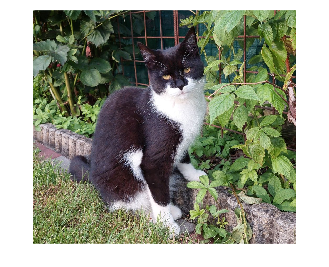

image=imread("macka.jpg");
imshow(image);

R = double(image(:,:,1));
G = double(image(:,:,2));
B = double(image(:,:,3));
[height,width] = size(R);
total= numel(R);

Obyčaná sepia

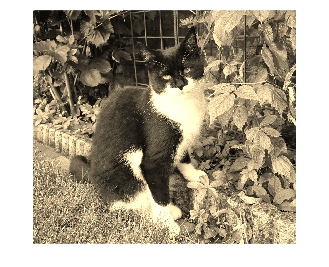

sepia1R   = (R * 0.393) + (G * 0.769) + (B * 0.189);
sepia1G = (R * 0.349) + (G * 0.686) + (B * 0.168);
sepia1B  = (R * 0.272) + (G * 0.534) + (B * 0.131);

sepia1R   = min(sepia1R, 255);
sepia1G = min(sepia1G, 255);
sepia1B  = min(sepia1B, 255);

imshow(uint8(cat(3, sepia1R, sepia1G, sepia1B)));

Desatuácia + hnedé zafarbenie

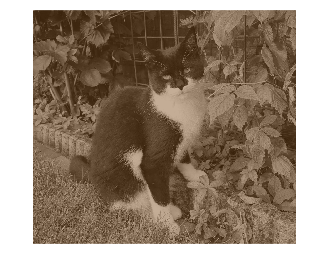

greyIMG=0.3*R+0.69*G+0.11*B;

brown=repmat(reshape(double([112,66,20]), 1, 1, 3), height, width);
intensity=0.5;

sepia2R   = greyIMG + (brown(:,:,1)-greyIMG)*intensity;
sepia2G = greyIMG + (brown(:,:,2)-greyIMG)*intensity;
sepia2B =greyIMG + (brown(:,:,3)-greyIMG)*intensity;

sepia2R   = min(sepia2R, 255);
sepia2G = min(sepia2G, 255);
sepia2B  = min(sepia2B, 255);

imshow(uint8(cat(3, sepia2R, sepia2G, sepia2B)));

Warm tone sepia

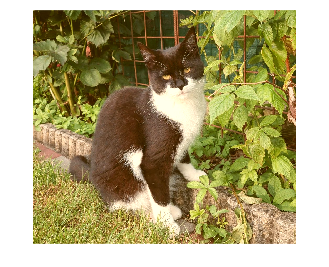

depth=20;
sepia3R   = R+ depth*2;
sepia3G = G+depth;
sepia3B =B-depth;

sepia3R   = min(sepia3R, 255);
sepia3G = min(sepia3G, 255);
sepia3B  = min(sepia3B, 255);

imshow(uint8(cat(3, sepia3R, sepia3G, sepia3B)));

berie do uvahy jas?

používa luminance calculation, resp. grayscale hodnoty, potom môžme ich použiť a 

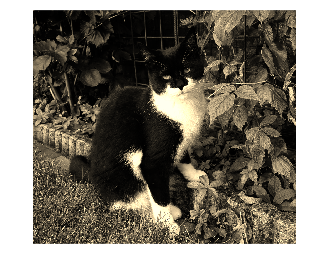

luminance = (0.3 * R+ 0.59 * G + 0.11 * B)/255;

sepia4R   = ((R * 0.393) + (G * 0.769) + (B * 0.189)) .* luminance;
sepia4G = ((R * 0.349) + (G * 0.686) + (B * 0.168)) .* luminance;
sepia4B  = ((R * 0.272) + (G * 0.534) + (B * 0.131)) .* luminance;

sepia4R   = min(sepia4R, 255);
sepia4G = min(sepia4G, 255);
sepia4B  = min(sepia4B, 255);

imshow(uint8(cat(3, sepia4R, sepia4G, sepia4B)));

test

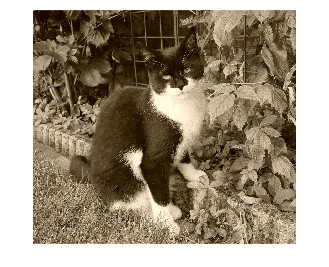

rg=19;
gb=27;

ar=0.70*rg+0.11*gb;
ag=ar-rg;
ab=ar-rg-gb;

l=(0.3 * R+ 0.59 * G + 0.11 * B);

pix=repmat(reshape(double([ar,ag,ab]), 1, 1, 3), height, width);

sepia5R   = l + ar;
sepia5G = l + ag;
sepia5B  = l + ab;

imshow(uint8(cat(3, sepia5R, sepia5G, sepia5B)));